clear; clc; close all; fclose('all');

**OFDM Parameters**

nfft = 1024;                    % nfft size equal to number of subcarriers
BW = 1000000000;                % Bandwidth of subcarriers (-F/2 F/2)
M = 8;                          % Baseband modulation order
cp_len = nfft/4;                % Cyclic Prefix length
ofdm_symbols =  10;               % Number of ofdm symbols to transmit
ebno_test = -5:2:30;
symbol_plot = 4;
rep = 4;                        % Repetition of pilots
pilot_index = [112:rep:913];    % Insert a pilot every 5 data sub-carriers
pilot_val = -0.7072+0.7072i;    % Set value of pilot subcarriers
data_index = 1:nfft;            % Index of data subcarriers
cw_tone = BW/nfft;
set_cw = 0; 
snr = 20;
% Set 224 zero padded subcarriers: 111 on lower and upper subcarriers
% and 2 on each side of carrier
zp_index = [1:111,914:1024];
multipath = [0 1 0.02 0.8];            % Multipath taps
no_multi = [1 0 0 0];
%multipath = [1 0.3 0.5 0];
data_index([zp_index,pilot_index]) = [];
scs = BW/nfft;
cfo = scs/2.1;
cfo = linspace(-cfo,cfo,ofdm_symbols);
%cfo = cfo*ones(1,ofdm_symbols);
plot_v = 0;
plot_symbol = 1;
pilot_carriers = length(pilot_index);   % Number of pilot carriers

num_data_bits = length(data_index)*ofdm_symbols

num_data_bits =         6010


**Modulate:**

[ofdm_signal_1,reference_pilot,mod_data,t,t2]=ofdm_transmit(nfft,BW,M,cp_len, ...
    ofdm_symbols,zp_index,pilot_index,0,1,1);
cw_signal = cos(2*pi*cw_tone*t2)'+i*sin(2*pi*cw_tone*t2)';

**Channel:**

cfo_err = [];
for i = 1:ofdm_symbols
    cfo_err = [cfo_err exp(1i*2*pi*cfo(i)*t2((i-1)*(cp_len+nfft)+1:i*(cp_len+nfft)))];
end
ofdm_signal = cfo_err'.*ofdm_signal_1;
[ofdm_signal,nvar] = awgn(ofdm_signal,snr,'measured');

**Scale:**

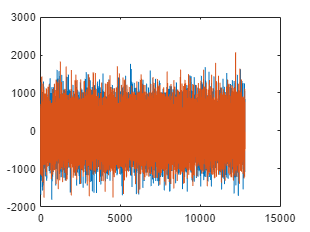

file = fopen('../../HW/modules/sim/equalizer_input_samples.txt','wt');
%file2 = fopen('../../HW/sims/cfo_correction_overlay/pre_cfo_data.txt','wt');
ofdm_scaled_signal = round(10000*ofdm_signal);
for i = 1:length(ofdm_signal)
    if i == length(ofdm_signal)
        fprintf(file,"%d, ",int16(real(ofdm_scaled_signal(i))));
        fprintf(file,"%d",int16(imag(ofdm_scaled_signal(i))));
        %fprintf(file2,"%d %d",int16(real(ofdm_scaled_signal(i))),int16(imag(ofdm_scaled_signal(i))));
    else
        fprintf(file,"%d, ",int16(real(ofdm_scaled_signal(i))));
        fprintf(file,"%d\n",int16(imag(ofdm_scaled_signal(i))));
        %fprintf(file2,"%d %d ",int16(real(ofdm_scaled_signal(i))),int16(imag(ofdm_scaled_signal(i))));
    end
end
fclose(file);
%fclose(file2);

file = fopen('../../HW/modules/sim/cw_input_samples.txt','wt');
%file2 = fopen('../../HW/sims/cfo_correction_overlay/cw_samples.txt','wt');
cw_scaled_signal = round(9000*cw_signal);
for i = 1:length(cw_signal)
    if i == length(cw_signal)
        fprintf(file,"%d, ",int16(real(cw_scaled_signal(i))));
        fprintf(file,"%d",int16(imag(cw_scaled_signal(i))));
        %fprintf(file2,"%d %d",int16(real(cw_scaled_signal(i))),int16(imag(cw_scaled_signal(i))));
    else
        fprintf(file,"%d, ",int16(real(cw_scaled_signal(i))));
        fprintf(file,"%d\n",int16(imag(cw_scaled_signal(i))));
        %fprintf(file2,"%d %d ",int16(real(cw_scaled_signal(i))),int16(imag(cw_scaled_signal(i))));
    end
end
fclose(file);
%fclose(file2);
figure(),plot(real(ofdm_scaled_signal)),hold on,plot(imag(ofdm_scaled_signal))

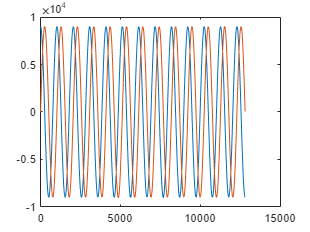

figure,plot(real(cw_scaled_signal)),hold on,plot(imag(cw_scaled_signal))

% file = fopen('../../HW/sims/cfo_correction_overlay/cfo_output_samples.txt','r');
% tmp_out = [];
% cfo_out1 = [];
% tmp1 = fscanf(file,"%d");
% for i=1:length(tmp1)/2
%     cfo_out1 = [cfo_out1 complex(tmp1(2*i-1),tmp1(2*i))];
% end
% figure(),plot(real(cfo_out1)),hold on,plot(imag(cfo_out1)),title('CFO Output on Target'),xlabel('Samples')

**Compare with Matlab: CFO Correction:**

ofdm_signal_1 = awgn(ofdm_signal_1,snr,'measured');
ofdm_signal_par_1 = reshape(ofdm_signal_1,[nfft+cp_len ofdm_symbols]);
cp_rm_1 = ofdm_signal_par_1;
cp_rm_1(1:cp_len,:) = [];
fft_out_1 = fft(cp_rm_1,nfft);
fft_out_1([zp_index,pilot_index],:) = [];

if set_cw == 1
    ofdm_scaled_signal = cw_scaled_signal;
end
ofdm_signal_par = reshape(ofdm_scaled_signal,[nfft+cp_len ofdm_symbols]);
cp_rm = ofdm_signal_par;
ofdm_signal_par_eq = cp_rm(:);
cp_rm(1:cp_len,:) = [];
ofdm_cfo_signal_par_eq = [];
cp_cfo_begin = [];cp_cfo_end=[];conj_val=[];tmp=[];sum_val=[];angle_val=[];cfo_est=[];freq=[];
for i = 1:ofdm_symbols
    cp_cfo_begin = [cp_cfo_begin ofdm_signal_par(1:cp_len,i)];% Obtain cyclic prefix at beginning of symbol
    cp_cfo_end = [cp_cfo_end (ofdm_signal_par(nfft+1:end,i))]; % Obtain cyclic prefix at end of symbol
    conj_val = [conj_val conj(cp_cfo_begin(1:cp_len,i))];
    tmp = [tmp complex(real(cp_cfo_end(1:cp_len,i).*conj_val(1:cp_len,i)), ...
        imag(cp_cfo_end(1:cp_len,i).*conj_val(1:cp_len,i)))];

**Vivado DDS:**


$$f_{\textrm{out}} =\frac{f_{\textrm{clk}} \cdot \Delta \theta }{2^{B_{0\left(n\right)} } }$$


Where $f_{\textrm{out}}$ is the frequency, in Hz, at the output of the DDS, $f_{\textrm{clk}}$ is the system clock, $B_{0\left(n\right)}$ is the phase width (number of bits) and $\Delta \theta$ is the phase increment.


$$\Delta \theta =\frac{f_{\textrm{out}} \cdot 2^{B_{0\left(n\right)} } }{f_{\textrm{clk}} }$$


**Frequency Resolution:**


$$\Delta f\frac{f_{\textrm{clk}} }{2^{B_{0\left(n\right)} } }$$


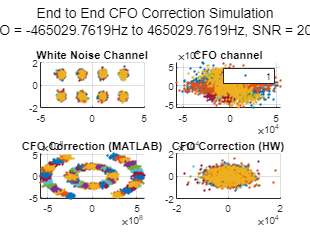


    sum_val = [sum_val sum(tmp(1:cp_len,i))];
    %angle_val = atan2(imag(sum_val),real(sum_val));
    angle_val = [angle_val angle(sum_val(i))];
    cfo_est = [cfo_est angle_val(i) * scs];
    %freq = exp(1i*cfo_est*t(1:nfft))';
    freq = [freq (cos(cfo_est(i)*t2((i-1)*1280+1:(i*1280)-cp_len))+1i*sin(cfo_est(i)*t2((i-1)*1280+1:(i*1280)-cp_len)))'];
    ofdm_cfo_signal_par_eq(:,i) = cp_rm(:,i).*freq(1:nfft,i)*2^14;
end
freq_scaled = freq * 2^14;

cp_rm_cfo = ofdm_cfo_signal_par_eq;

fft_out = fft(cp_rm,nfft);
fft_out_cfo = fft(cp_rm_cfo,nfft);                   % CFO correction

pilot_recovered = fft_out_cfo(pilot_index,:);

data_carriers_out = fft_out;
data_carriers_out([zp_index,pilot_index],:) = [];
data_carriers_out_cfo = fft_out_cfo;
data_carriers_out_cfo([zp_index,pilot_index],:) = [];   % Remove pilot and ZP carriers


% ZF Equalization
estimated_pilot_cfo = pilot_recovered.*conj(reference_pilot);
%estimated_pilot_cfo = angle(pilot_recovered_cfo.*conj(reference_pilot)./abs(reference_pilot));
fft_out_cfo2 = fft_out_cfo;
for i = 1:pilot_carriers
    zf = pilot_recovered(i,:)./reference_pilot(i,:);
    mmse = (conj(zf))./(zf.*conj(zf)+nvar);
    %estimated_pilot = angle(pilot_recovered_cfo(i,:).*conj(reference_pilot(i,:))./abs(reference_pilot(i,:)));
    %fft_out_cfo(pilot_index(i):pilot_index(i)+rep-1,:) = fft_out_cfo(pilot_index(i):pilot_index(i)+rep-1,:)./estimated_pilot;
    fft_out_cfo(pilot_index(i):pilot_index(i)+rep-1,:) = fft_out_cfo(pilot_index(i):pilot_index(i)+rep-1,:).*mmse;

end
equalized_cfo = fft_out_cfo;
equalized_cfo([zp_index,pilot_index],:) = [];  % Remove pilot and ZP carriers
demod_data_cfo_eq = qamdemod(equalized_cfo,M);
demod_data = qamdemod(data_carriers_out,M);

file = fopen('../../HW/modules/sim/mixer_vivado_samples.txt','r');
%file = fopen('../../HW/sims/cfo_correction_overlay/cfo_output_samples.txt','r');
tmp_out = [];
cfo_out1 = [];
for i = 1:nfft*ofdm_symbols*2
    tmp1 = fscanf(file,"%d");
    tmp2 = fscanf(file,",%d");
    tmp_out = complex(tmp1,tmp2);
    cfo_out1 = [cfo_out1 tmp_out];
end
% file = fopen('../../HW/sims/cfo_correction_overlay/cfo_output_samples.txt','r');
% tmp11 = fscanf(file,"%d");
% cfo_out11 = [];
% for i = 1:nfft*ofdm_symbols/2
%     tmp2 = tmp11(2*i);
%     tmp_out = complex(tmp11(2*i-1),tmp2);
%     cfo_out11 = [cfo_out11 tmp_out];
% end
%cfo_out1 = [cfo_out1 cfo_out1];

if length(cfo_out1)~=nfft*ofdm_symbols*2
    display("ERROR: Run Vivado sim")
    cfo_out1 = zeros(1,nfft*ofdm_symbols);
end
cfo_out1(ofdm_symbols*nfft+1:ofdm_symbols*nfft*2) = [];
cp_rm_hw = reshape(cfo_out1',[nfft ofdm_symbols]);
%cp_rm_hw = reshape(cfo_out1',[nfft ofdm_symbols*2]);
fft_out_hw = fft(cp_rm_hw,nfft);
fft_out_hw2 = fft_out_hw(:,1:ofdm_symbols);
data_carriers_hw = fft_out_hw;
data_carriers_hw([zp_index,pilot_index],:) = [];
% ZF Equalization
pilot_recovered_cfo = fft_out_hw(pilot_index,:);
for i = 1:pilot_carriers
    zf = pilot_recovered_cfo(i,:)./reference_pilot(i,:);
    mmse = (conj(zf))./(zf.*conj(zf)+nvar);
    fft_out_hw2(pilot_index(i):pilot_index(i)+rep-1,:) = fft_out_hw2(pilot_index(i):pilot_index(i)+rep-1,:).*mmse;
end
equalized_hw = fft_out_hw2;
equalized_hw([zp_index,pilot_index],:) = [];
demod_data_hw = qamdemod(equalized_hw,M);

    figure(),subplot(2,2,1),scatter(real(fft_out_1),imag(fft_out_1),'.'),grid on, title('White Noise Channel')
    subplot(2,2,2),scatter(real(data_carriers_out),imag(data_carriers_out),'.'),grid on,title('CFO channel')
    legend('1')
    subplot(2,2,3),scatter(real(data_carriers_out_cfo),imag(data_carriers_out_cfo),'.','LineWidth',2),grid on,title('CFO Correction (MATLAB)')
    subplot(2,2,4),scatter(real(data_carriers_hw),imag(data_carriers_hw),'.','LineWidth',2),grid on,title('CFO Correction (HW)')
    sgtitle({'End to End CFO Correction Simulation',['CFO = ',num2str(cfo(1)),'Hz to ',num2str(cfo(end)),'Hz, SNR = ',num2str(snr),'dB']})

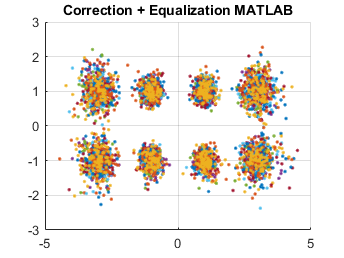

    %sgtitle({'End to End CFO Correction Simulation',['CFO = ',num2str(cfo(1)),'Hz, SNR = ',num2str(snr),'dB']})
figure(),scatter(real(equalized_cfo),imag(equalized_cfo),'.'),grid on,title("Correction + Equalization MATLAB")

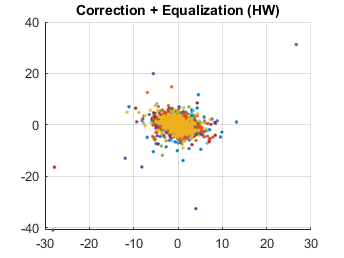

figure(),scatter(real(equalized_hw),imag(equalized_hw),'.'),grid on,title("Correction + Equalization (HW)")

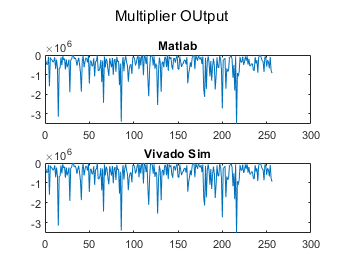

file = fopen('../../HW/modules/sim/info.txt','wt');
fprintf(file,"%d",ofdm_symbols);
file = fopen('../../HW/modules/sim/cp_begin_samples.txt','wt');
for k = 1:ofdm_symbols
    for i = 1:cp_len
        if ((i == cp_len) && (k == ofdm_symbols))
            fprintf(file,"%d, ",int16(real(cp_cfo_begin(i,k))));
            fprintf(file,"%d",int16(imag(cp_cfo_begin(i,k))));
        else
            fprintf(file,"%d, ",int16(real(cp_cfo_begin(i,k))));
            fprintf(file,"%d\n",int16(imag(cp_cfo_begin(i,k))));
        end
    end
end
file = fopen('../../HW/modules/sim/cp_end_samples.txt','wt');
for k = 1:ofdm_symbols
    for i = 1:cp_len
        if ((i == cp_len) && (k == ofdm_symbols))
            fprintf(file,"%d, ",int16(real(cp_cfo_end(i,k))));
            fprintf(file,"%d",int16(imag(cp_cfo_end(i,k))));
        else
            fprintf(file,"%d, ",int16(real(cp_cfo_end(i,k))));
            fprintf(file,"%d\n",int16(imag(cp_cfo_end(i,k))));
        end
    end
end
file = fopen('../../HW/modules/sim/cp_conj_samples.txt','wt');
for k = 1:ofdm_symbols
    for i = 1:cp_len
        if ((i == cp_len) && (k == ofdm_symbols))
            fprintf(file,"%d, ",int16(real(conj_val(i,k))));
            fprintf(file,"%d",int16(imag(conj_val(i,k))));
        else
            fprintf(file,"%d, ",int16(real(conj_val(i,k))));
            fprintf(file,"%d\n",int16(imag(conj_val(i,k))));
        end
    end
end
file = fopen('../../HW/modules/sim/mult_samples.txt','wt');
for k = 1:ofdm_symbols
    for i = 1:cp_len
        if ((i == cp_len) && (k == ofdm_symbols))
            fprintf(file,"%d, ",int32(real(tmp(i,k))));
            fprintf(file,"%d",int32(imag(tmp(i,k))));
        else
            fprintf(file,"%d, ",int32(real(tmp(i,k))));
            fprintf(file,"%d\n",int32(imag(tmp(i,k))));
        end
    end
end
file = fopen('../../HW/modules/sim/mult_verif_samples.txt','r');
tmp_out = [];
tmp_out1 = [];
for i = 1:cp_len
    tmp1 = fscanf(file,"%d");
    tmp2 = fscanf(file,",%d");
    tmp_out = complex(tmp1,tmp2);
    tmp_out1 = [tmp_out1 tmp_out];
end
figure(),subplot(2,1,1),plot(int32(real(tmp(1:cp_len,1)))),title('Matlab')
subplot(),subplot(2,1,2),plot(int32(real(tmp_out1))),title('Vivado Sim')
sgtitle('Multiplier OUtput')

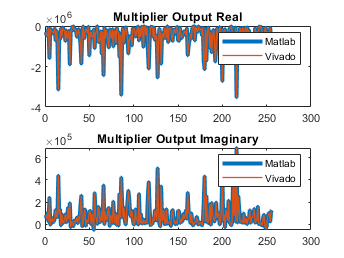

figure(),subplot(2,1,1),plot(int32(real(tmp(1:cp_len,1))),'LineWidth',3),hold on,plot(int32(real(tmp_out1)),'LineWidth',1),title('Multiplier Output Real'),legend('Matlab','Vivado')
subplot(2,1,2),plot(int32(imag(tmp(1:cp_len,1))),'LineWidth',3),hold on,plot(int32(imag(tmp_out1)),'LineWidth',1),title('Multiplier Output Imaginary'),legend('Matlab','Vivado')

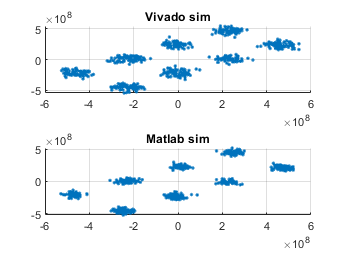

file = fopen('../../HW/modules/sim/sum_samples.txt','wt');
for i = 1:ofdm_symbols
    if i == ofdm_symbols
        fprintf(file,"%d, ",int32(real(sum_val(i))));
        fprintf(file,"%d",int32(imag(sum_val(i))));
    else
        fprintf(file,"%d, ",int32(real(sum_val(i))));
        fprintf(file,"%d\n",int32(imag(sum_val(i))));
    end
end
file = fopen('../../HW/modules/sim/angle_samples.txt','wt');
for i = 1:ofdm_symbols
    if i == ofdm_symbols
        fprintf(file,"%d, ",angle_val(i));
    else
        fprintf(file,"%d, ",angle_val(i));
    end
end
file = fopen('../../HW/modules/sim/dds_samples.txt','wt');
for k = 1:ofdm_symbols
    for i = 1:nfft
        if ((i == nfft) && (k == ofdm_symbols))
            fprintf(file,"%.0f, ",int32(real(freq_scaled(i,k))));
            fprintf(file,"%.0f",int32(imag(freq_scaled(i,k))));
        else
            fprintf(file,"%.0f, ",real(freq_scaled(i,k)));
            fprintf(file,"%.0f\n",imag(freq_scaled(i,k)));   
        end
    end
end
file = fopen('../../HW/modules/sim/mixer_samples.txt','wt');
for k = 1:ofdm_symbols
    for i = 1:nfft
        if ((i == nfft && k == ofdm_symbols))
            fprintf(file,"%.0f, ",real(ofdm_cfo_signal_par_eq(i)));
            fprintf(file,"%.0f",imag(ofdm_cfo_signal_par_eq(i)));
        else
            fprintf(file,"%.0f, ",real(ofdm_cfo_signal_par_eq(i)));
            fprintf(file,"%.0f\n",imag(ofdm_cfo_signal_par_eq(i)));    
        end
    end
end
file = fopen('../../HW/modules/sim/dds_vivado_samples.txt','r');
tmp_out = [];
cfo_out1 = [];
for i = 1:nfft
    tmp1 = fscanf(file,"%d");
    tmp2 = fscanf(file,",%d");
    tmp_out = complex(tmp1,tmp2);
    cfo_out1 = [cfo_out1 tmp_out];
end
cfo_out1 = cfo_out1';
cp_rm = cp_rm(1:nfft);
dds_signal_par_eq = cp_rm(:).*cfo_out1;
mat_signal_par_eq = cp_rm(:).*freq_scaled(1:nfft,1);
fft_out_dds = fft(dds_signal_par_eq,nfft);
fft_out_mat = fft(mat_signal_par_eq,nfft);
pilot_recovered_dds = fft_out_dds(pilot_index,:);
data_carriers_out_dds = fft_out_dds;
data_carriers_out_dds([zp_index,pilot_index]) = [];
data_carriers_out_mat = fft_out_mat;
data_carriers_out_mat([zp_index,pilot_index]) = [];
figure(),subplot(2,1,1),scatter(real(data_carriers_out_dds),imag(data_carriers_out_dds),'.','LineWidth',2),grid on,title('Vivado sim')
subplot(2,1,2),scatter(real(data_carriers_out_mat),imag(data_carriers_out_mat),'.','LineWidth',2),grid on,title('Matlab sim')

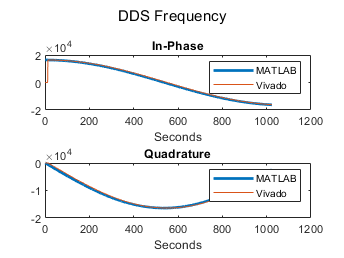

figure(),subplot(2,1,1),plot(real(freq_scaled(1:nfft,plot_symbol)),'LineWidth',2)
hold on,plot(real(cfo_out1)),legend('MATLAB','Vivado'),xlabel('Seconds'),title('In-Phase')
subplot(2,1,2),plot(imag(freq_scaled(1:nfft,plot_symbol)),'LineWidth',2),xlabel('Seconds'),title('Quadrature')
hold on,plot(imag(cfo_out1)),legend('MATLAB','Vivado')
sgtitle('DDS Frequency')

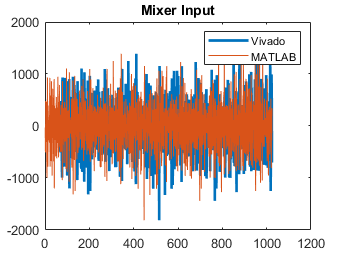

file = fopen('../../HW/modules/sim/mixer_out_samples.txt','r');
tmp_out = [];
cfo_out1 = [];
for i = 1:nfft
    tmp1 = fscanf(file,"%d");
    tmp2 = fscanf(file,",%d");
    tmp_out = complex(tmp1,tmp2);
    cfo_out1 = [cfo_out1 tmp_out];
end
cfo_out1 = cfo_out1';
fclose('all');
figure(),plot(real(cfo_out1),'LineWidth',2),hold on,plot(real(cp_rm)),title('Mixer Input'),legend('Vivado','MATLAB')

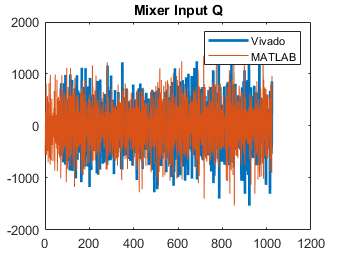

figure(),plot(imag(cfo_out1),'LineWidth',2),hold on,plot(imag(cp_rm)),title('Mixer Input Q'),legend('Vivado','MATLAB')

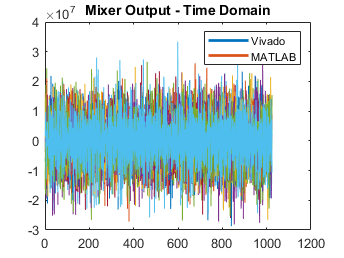

figure(),plot(real(cp_rm_hw),'LineWidth',2),hold on,plot(real(cp_rm_cfo)),title('Mixer Output - Time Domain'),legend('Vivado','MATLAB')